# **Materials classification - A1**

# Bayesian Networks

clc; clear all; close all;

## Import dataset

image_data_folder = "Data\image\";
image = Images_import(image_data_folder);

% Each row of each matrix contains the paths of the images of an specific material, being
% the order of the rows: fabric, foliage, glass, leather, metal, paper,
% plastic, tone, water and wood

### Create image set

% Apply the mask and save only the foreground object
imgData = [];
for idx = 1:length(image)
    tempImg = imread(image(idx).path);
    imgData{idx} = tempImg;
end

clearvars tempImg idx image_data_folder;

## Feature Extraction

### Feature 1: Entropy measure

entropyVals = [];
for idx = 1:length(imgData)
    entropyVals(idx) = entropy(double(im2gray(imgData{idx}(:))));
end
save("entropyVals.mat", "entropyVals");

### Feature 2: Number of edges

edgeCount = [];
for idx = 1:length(imgData)
    bw = edge(im2gray(imgData{idx}),'canny');
    edgeCount(idx) = nnz(bw);
end
save("edgeCount.mat", "edgeCount");

### Feature 3: Std. deviation of image

for idx = 1:length(imgData)
    imgDev(idx) = std(double(im2gray(imgData{idx}(:))));
end
save("imgDev.mat", "imgDev");

### Feature 4: Mean of RGB 

imgMean = [];
for idx = 1:length(imgData)
    a = double(imgData{idx});
    imgMean(idx, :) = mean(reshape(a, [], 3, 1));
end
imgMean = imgMean';
save("imgMean.mat", "imgMean");

### Feature 5: HOG features 

for idx = 1:length(imgData)
    imgHog(idx,1) = sum(extractHOGFeatures(imgData{idx}));
    imgHog(idx,2) = max(extractHOGFeatures(imgData{idx}));
    imgHog(idx,3) = mean(extractHOGFeatures(imgData{idx}));
end
imgHog = imgHog';
save("imgHog.mat", "imgHog");

### Feature 6: SURF features 

for idx = 1:length(imgData)
    points = detectSURFFeatures(im2gray(imgData{idx}));
    if size(points,1) == 0
        imgSURF(idx,1) = 0;
        imgSURF(idx,2) = 0;
        imgSURF(idx,3) = 0;
    else
        imgSURF(idx,1) = sum(sum(extractFeatures(im2gray(imgData{idx}),points)));
        imgSURF(idx,2) = max(max(extractFeatures(im2gray(imgData{idx}),points)));
        imgSURF(idx,3) = mean(mean(extractFeatures(im2gray(imgData{idx}),points)));
    end
end
imgSURF = imgSURF';
save("imgSURF.mat", "imgSURF");

### Feature 7: Number of objects 

for idx = 1:length(imgData)
    imgEuler(idx) = bweuler(im2bw(imgData{idx}));
end
save("imgEuler.mat", "imgEuler");

### Feature 8: HSV color scale

imgHSV = [];
for idx = 1:length(imgData)
    [~, ~, d] = size(imgData{1, idx});
    if d > 1   
        a = rgb2hsv(imgData{1,idx});
        imgHSV(idx, :) = mean(reshape(a, [], 3, 1));
    end
end
imgHSV = fillmissing(imgHSV, "constant", 0);
imgHSV = imgHSV';
save("imgHSV.mat", "imgHSV");

## PCA and data discretization

clc; clear all; close all;

for mmm = 10:10 % No segments
for m = 8:8

rng('default')
clearvars -except mmm m accuracy
load edgeCount.mat
load entropyVals.mat
load imgDev.mat
load imgHog.mat
load imgMean.mat
load imgEuler.mat
load imgSURF.mat
load imgHSV.mat

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];
features = [edgeCount; entropyVals; imgDev; imgHog; imgMean; imgSURF; imgEuler; imgHSV]';
data0 = features;

% append new column class, represented for every 90 sequential obs
classCount = 1;
for idx = 1:length(data0)
    data0(idx,size(features,2) + 1) = classCount;
    if mod(idx,100) == 0
        classCount = classCount + 1;
    end
end

% The data shows high positive and negative correlation between some classes.
% Hence, apply PCA before training the BN model
[~, scores] = pca(data0(:,1:end-1));
data = [];
data = scores(:,1:m);
nseg = mmm;
data(:,end+1) = data0(:,end);

% dimensions of data
featurecount = size(data,2)-1;
classcount = 10;

for i = 1:length(data(1,1:end-1))

    var     = data(:,i);
    minVal  = min(var);
    maxVar  = max(var);
    segLength = maxVar - minVal;
    subSegLength = segLength/nseg;
    seg(1).LB = minVal;

    for ii = 1:nseg
        if ii ~= 1
            seg(ii).LB = seg(ii-1).LB + subSegLength + 0.0001;
        end
    end

    for ii = 1:nseg-1
        idxCurrent = intersect(find(data(:,i)>=seg(ii).LB), find(data(:,i)<seg(ii+1).LB));
        data2(idxCurrent,i) = ii;
    end
    idxCurrent = find(data(:,i)>seg(ii+1).LB);
    data2(idxCurrent,i) = ii+1;
end

data2(:,end+1) = data(:,end);


## Data Division

[row, col]      = size(data2);

varLabels = ["PC1", "PC2", "PC3", "PC4", "PC5", "PC6", "PC7", "PC8", "class"];
figure;
ii = 1;
for i = 1:col
    subplot(2, col, i);
    histogram(data(:,i)); title("Original " + varLabels(i));

    subplot(2, col, i+col);
    histogram(data2(:,i)); title("Discretized " + varLabels(i));
end


% Test and calibration in the partition below.
partitionRatio = 0.2;
c       = cvpartition(size(data2,1),'Holdout',partitionRatio);
idxCal = test(c);
idxTrain  = training(c);
dataTrain    = data2(idxTrain,  :);
dataCal = data2(idxCal, :);


## BN: Learn structure and train

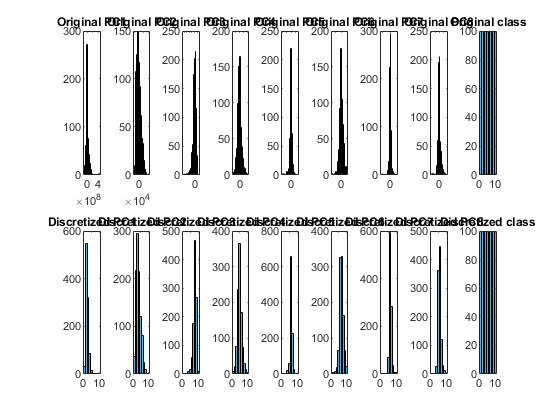

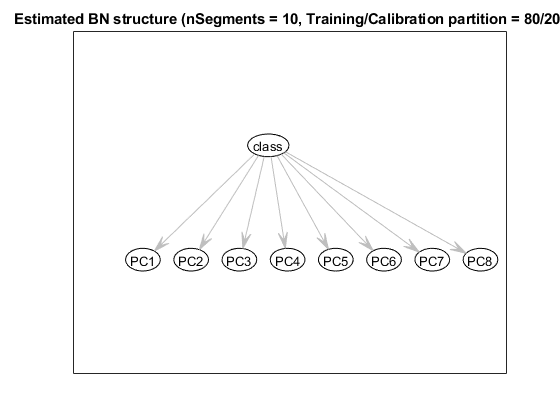

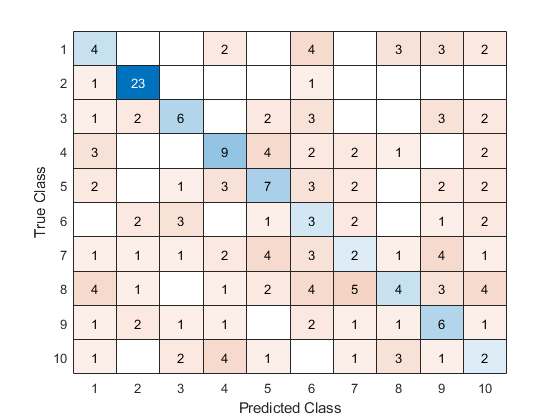

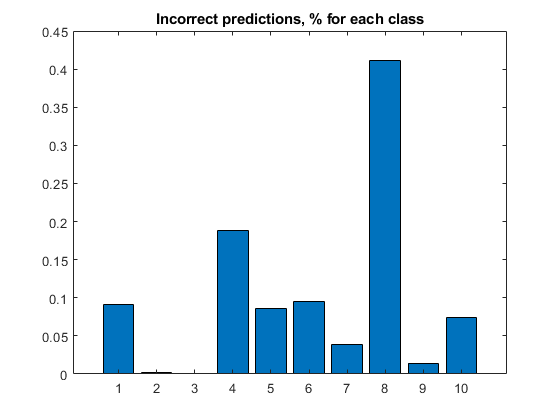

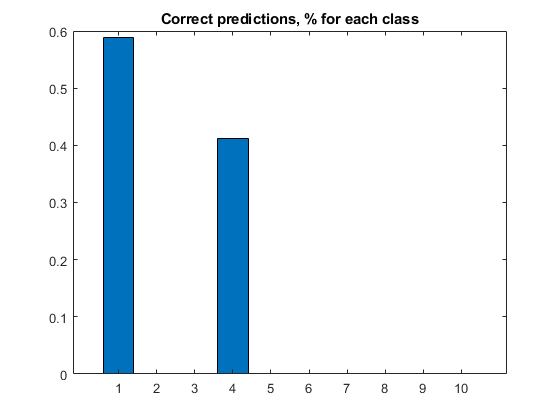

[row, col]      = size(dataTrain);

ncases  = row;
cases   = cell(col, ncases);
cases   = num2cell(dataTrain');

for i = 1:featurecount+1
    varI(i).idx = i;
    if i == featurecount+1
        varI(i).name = "Class";
    else
        varI(i).name = "PC " + string(i);
    end

end
node_sizes = [ones(1,featurecount)*nseg, classcount];

DAGhat = false(featurecount+1, featurecount+1);
DAGhat(featurecount+1, 1:featurecount) = true;

BNtemp = mk_bnet(DAGhat, node_sizes);
for i = 1:featurecount+1
    BNtemp.CPD{varI(i).idx} = tabular_CPD(BNtemp, varI(i).idx);
end

BNhat = learn_params(BNtemp, cases);

N = featurecount+1;
CPThat = cell(1, N);
for i = 1:N
  s = struct(BNhat.CPD{i});
  CPThat{i} = s.CPT;
end

figure;
draw_graph(BNhat.dag, varLabels);
title(sprintf("Estimated BN structure (nSegments = %d, Training/Calibration partition = %d/%d)", nseg, 100-partitionRatio*100, partitionRatio*100));

for i = 1:size(dataCal,1)
    engine = jtree_inf_engine(BNhat);
    
    evidence = cell(1,N);
    for mm = 1:featurecount
        evidence{varI(mm).idx} = dataCal(i,mm);
    end
    [engine, loglik] = enter_evidence(engine, evidence);
    
    marg = marginal_nodes(engine, featurecount+1);
    resultsmatrix(:,i) = marg.T;

    [~,ind] = max(marg.T);
    result(i) = ind;
end

result;

C = confusionmat(dataCal(:,end),result);
figure
confusionchart(C)

accuracy(m, mmm) = sum(dataCal(:,end)==result')/length(result);

ind = find(dataCal(:,end)~=result');
wrong1 = resultsmatrix(:,ind(1));

dataCal(ind(1),end);

figure
bar(wrong1);
title("Incorrect predictions, % for each class");

ind = find(dataCal(:,end)==result');
wrong1 = resultsmatrix(:,ind(1));

dataCal(ind(1),end);

figure;
bar(wrong1);
title("Correct predictions, % for each class");

end
end

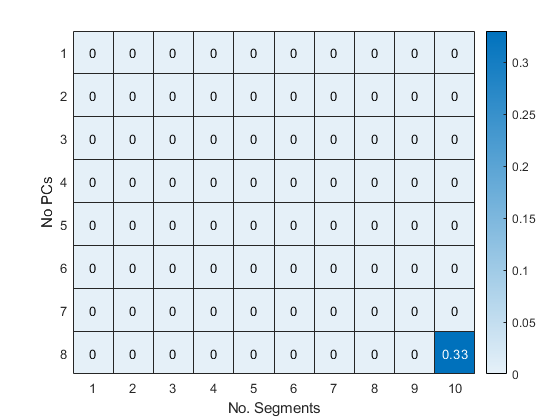


figure; heatmap(accuracy);
xlabel("No. Segments");
ylabel("No PCs");

% Max accuracy of 33% obtained with 10 segments and 8 PCs